## Figure 9:  Spectral components

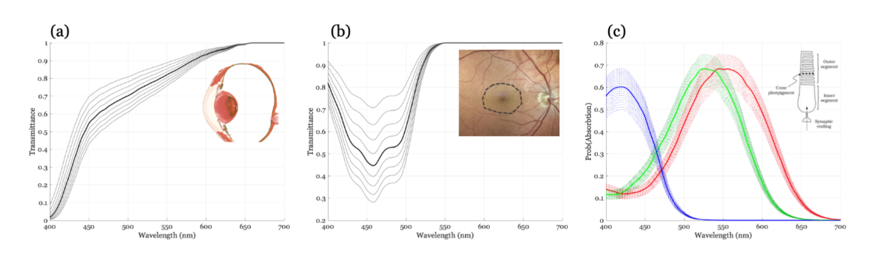

Spectral properties of visual system components that determine the input-referred quantum efficiency of the cones. (a) The crystalline lens dramatically reduces the fraction of short wavelength light transmitted to the retina. The optical density of the lens varies between people and with age. (b) The macular pigment is present in foveal, but not peripheral, regions of the retina. The pigment density in the fovea varies across people and with disease. (c) The optical density of the cone photopigment varies between people and across the retina. In all panels the dark solid curve is the standard and lighter curves are variations

### First the lens

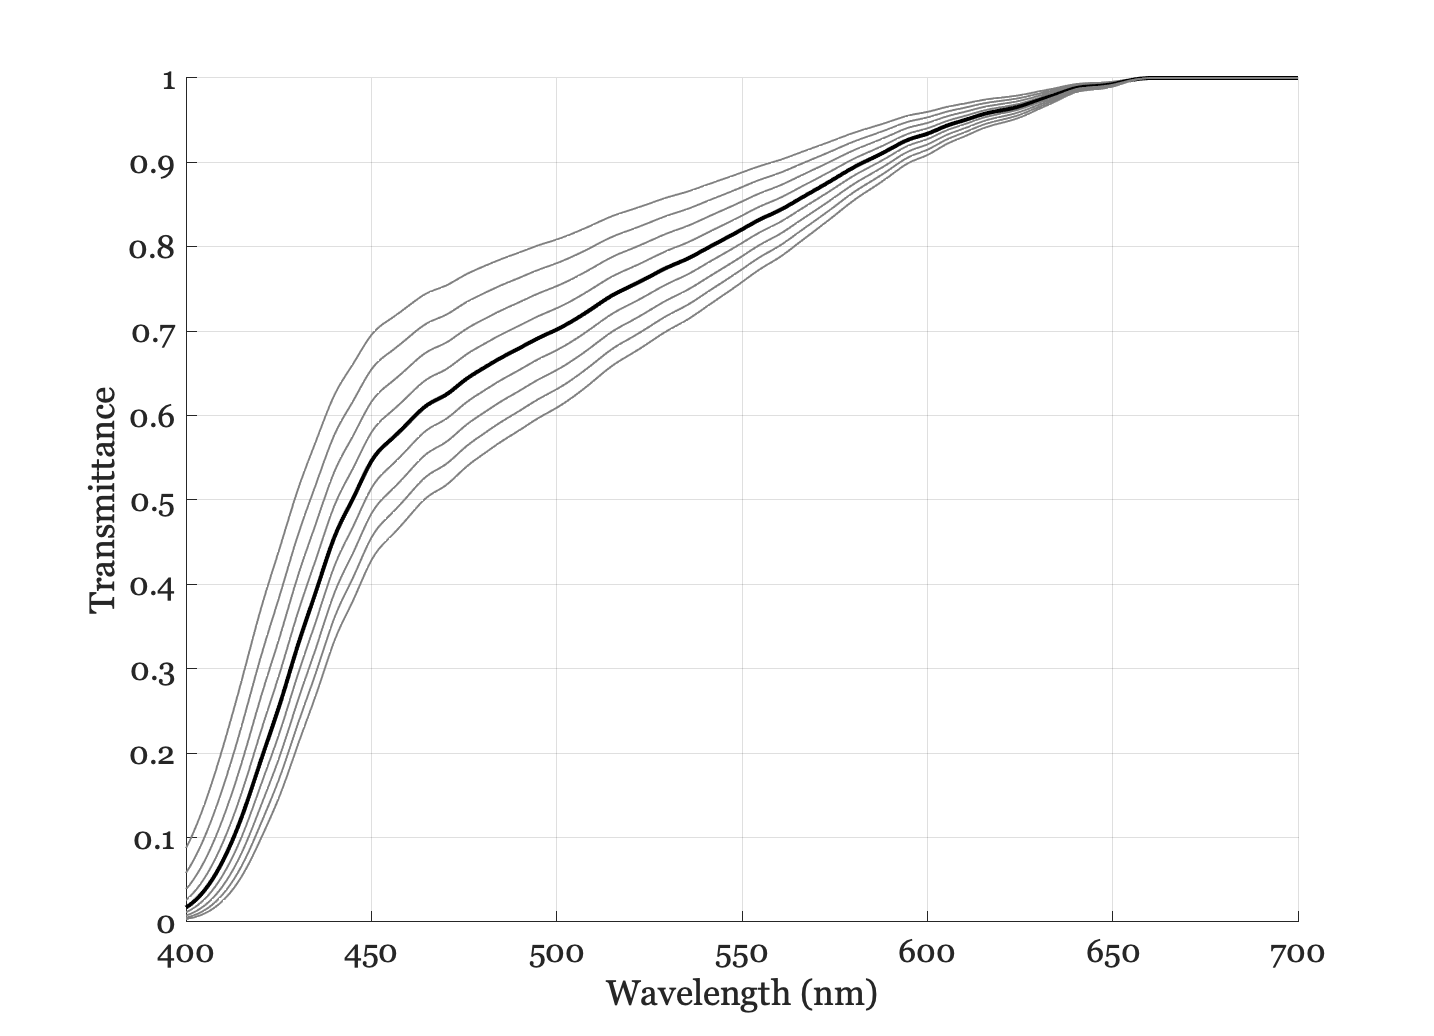

wave = 400:1:700;
thisLens = Lens;
thisLens.set('wave',wave);

% Base lens density
lensDensity = thisLens.density;

ieNewGraphWin;
hold on;

% Vary around the base
for dd = -0.4:0.1:0.4
    thisLens.density = lensDensity + dd;
    t = thisLens.transmittance;
    p = plot(wave,t,'color',[0.5 0.5 0.5]);
    if dd == 0
        p.LineWidth = 2;
        p.Color = 'k';
    end
end
grid on;
xlabel('Wavelength (nm)');
ylabel('Transmittance');

### Macular pigment

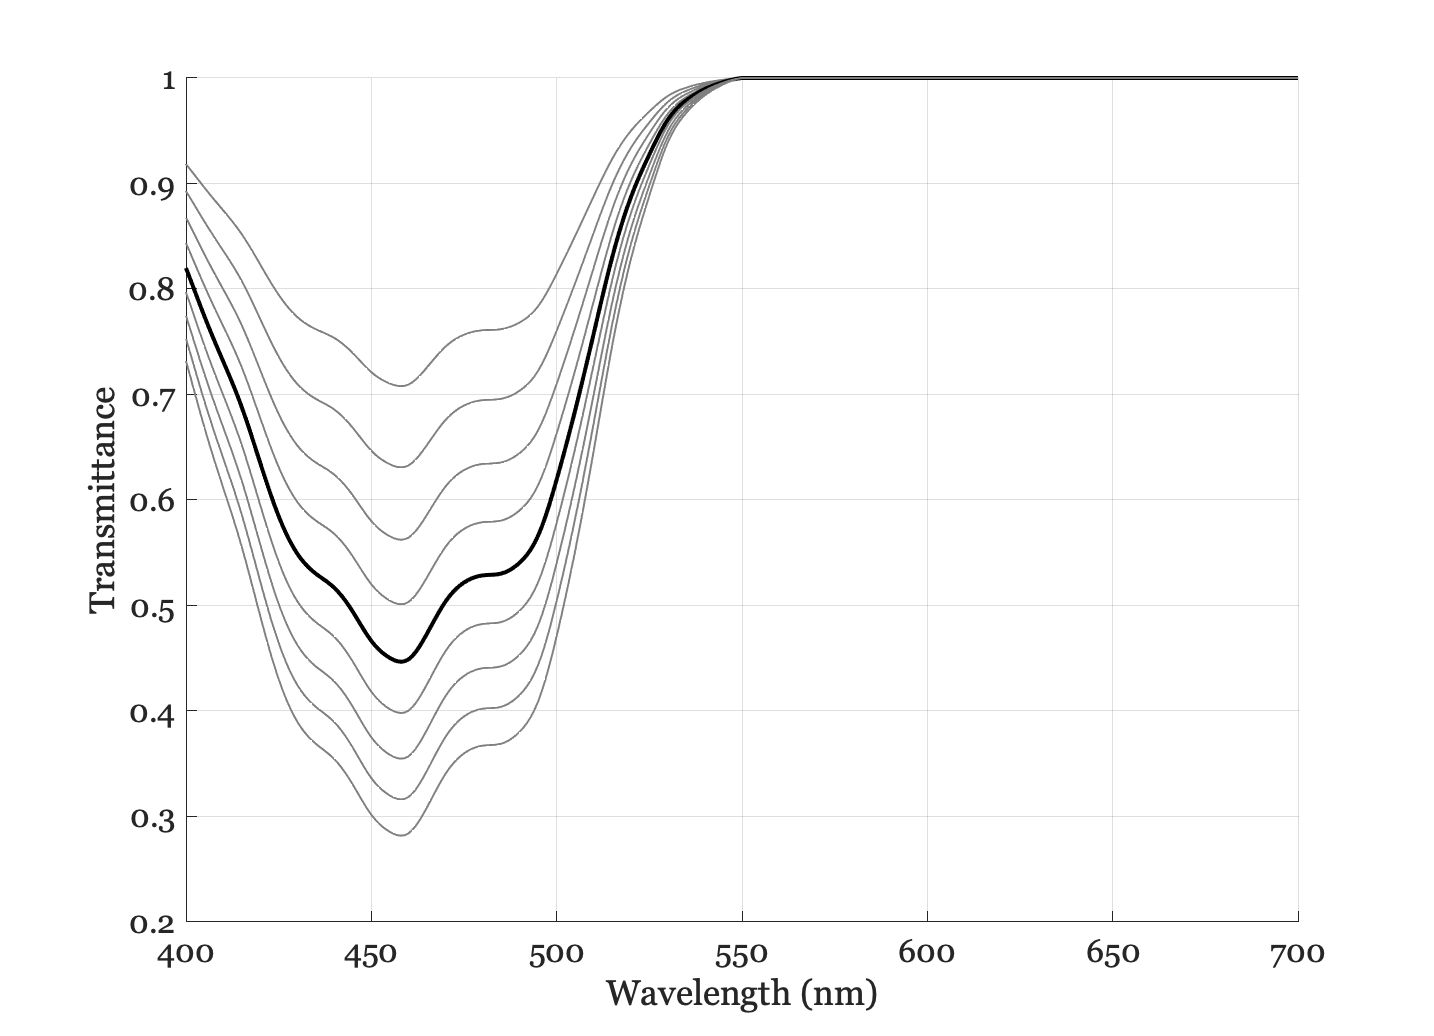

thisM = Macular;
thisM.wave = wave;

% Base
macularDensity = thisM.density;

ieNewGraphWin;
hold on;
% Vary around base
for dd = -0.2:0.05:0.2
    thisM.density = dd + macularDensity;
    t = thisM.transmittance;
    p = plot(wave,t,'color',[0.5 0.5 0.5]);
    if dd == 0
        p.LineWidth = 2;
        p.Color = 'k';
    end
end
grid on;
xlabel('Wavelength (nm)');
ylabel('Transmittance');

### Cones pigment

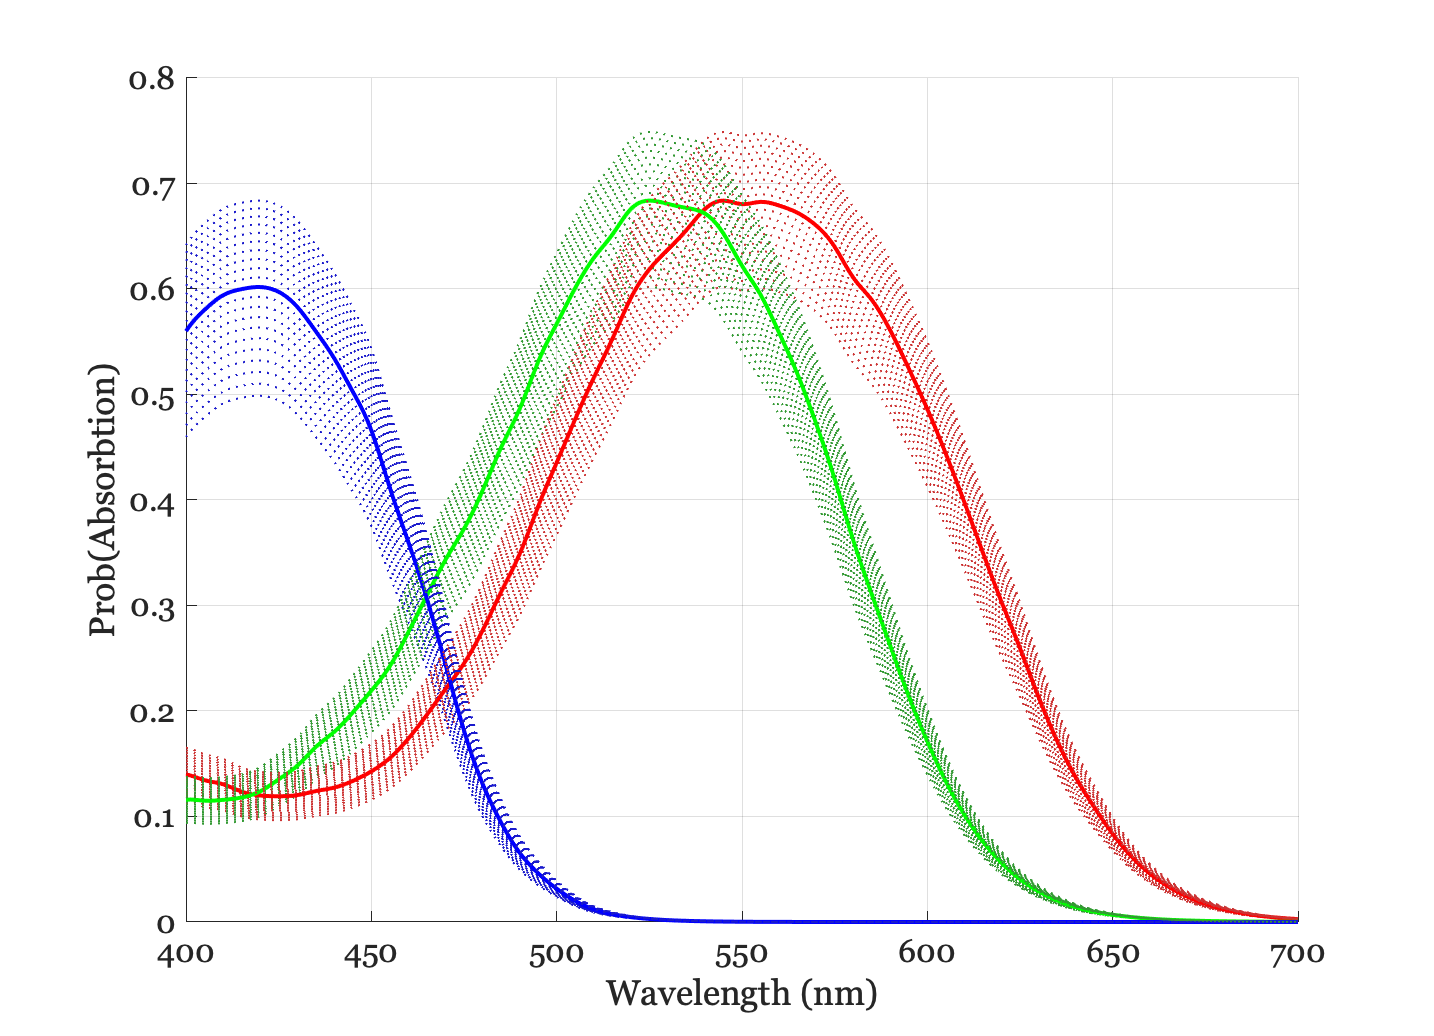

conePigments = photoPigment;
conePigments.wave = wave;
% Base
pigmentDensity = conePigments.opticalDensity;

ieNewGraphWin;
hold on;

thisColor = [0.8 0.2 0.2; 0.2 0.6 0.2; 0.1 0.1 0.8];
peakColor = {'r','g','b'};
% Vary around base
for dd=-0.1:0.01:0.1
    conePigments.opticalDensity = pigmentDensity + dd*ones(size(pigmentDensity));
    p = plot(conePigments.wave,conePigments.absorptance);
    for ii=1:3
        p(ii).Color = thisColor(ii,:);
        p(ii).LineStyle = ':';
    end
    
    if dd==0
        for ii=1:3
            p(ii).LineWidth = 2;
            p(ii).Color = peakColor{ii};
            p(ii).LineStyle = '-';
        end
    end
end
grid on; xlabel('Wavelength (nm)'); ylabel('Prob(Absorbtion)');

### Fundamentals

cm = cMosaic;

min cone aperture diameter = 1.694712 microns


wave = 400:1:700;
cm.wave = wave;
thisLens.wave = wave;

## Fundamentals and nearby, varying lens, macular, and pigment

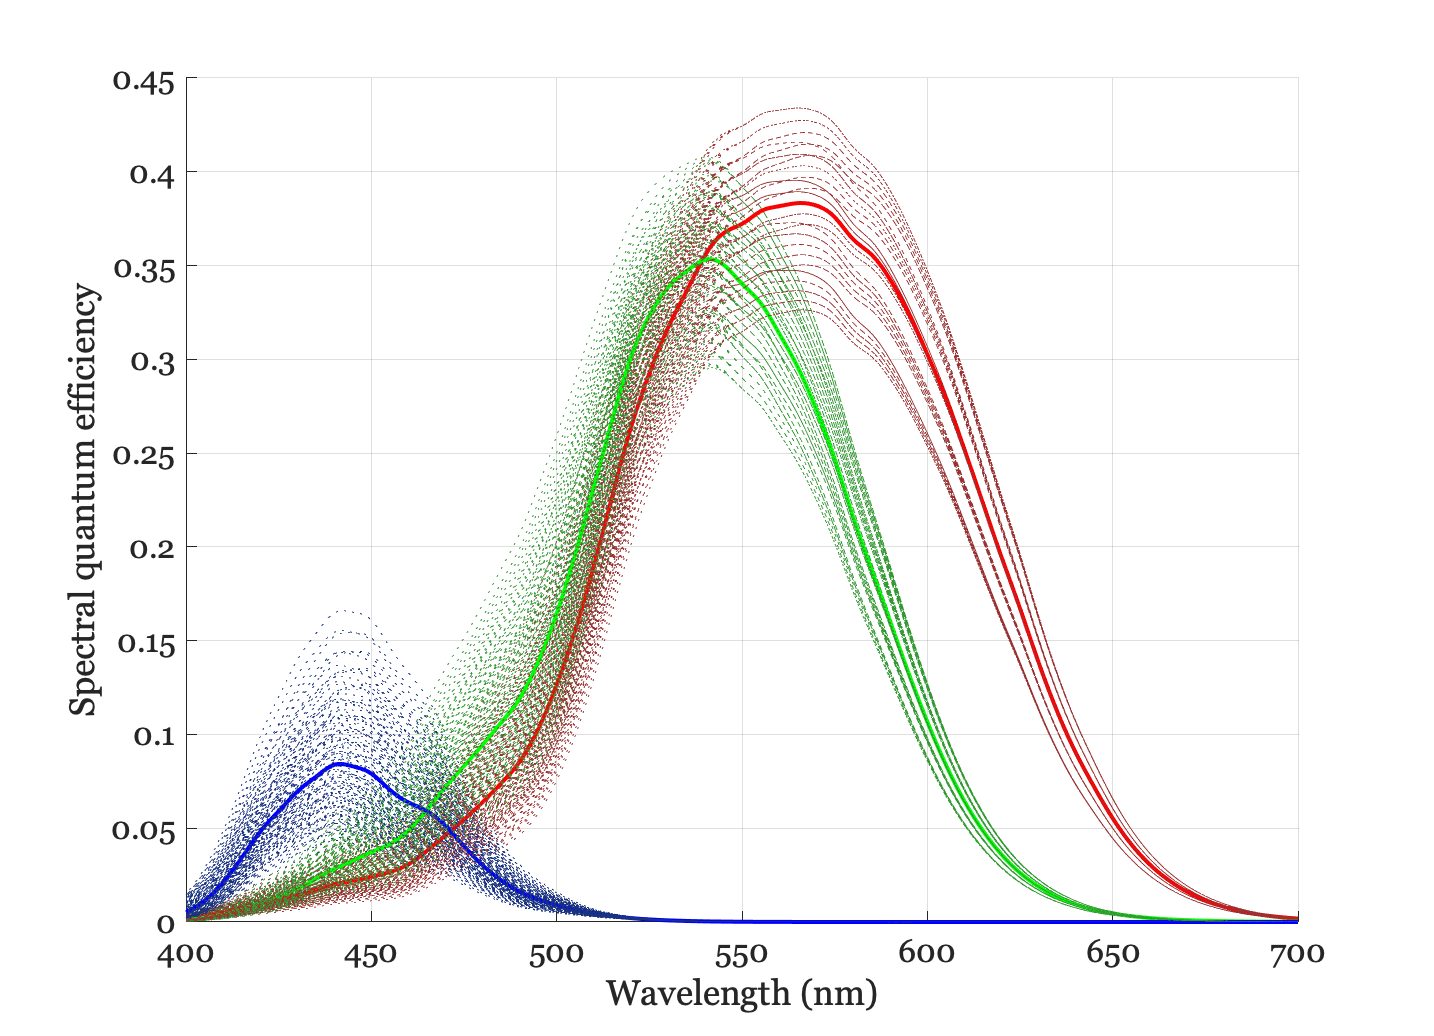

hdl = ieNewGraphWin;
hold on;
thisColor = [0.6 0.2 0.2; 0.2 0.6 0.2; 0.1 0.2 0.5];

for ll = -0.2:0.1:0.2
    thisLens.density = lensDensity + ll;
    for mm = -0.2:0.1:0.2
        cm.macular.density = macularDensity + mm;
        for pp = -0.1:0.05:0.1
            cm.pigment.opticalDensity = pigmentDensity + pp*ones(size(pigmentDensity));
            [~,fighdl] = cm.plot('spectral qe',[],'lens',thisLens,'hdl',hdl);
            p = fighdl.Children.Children;
            
            if ll==0 && mm == 0 && pp == 0
                % The standard.
                for ii=1:3
                    p(ii).LineWidth = 2;
                    p(ii).Color = peakColor{4-ii};                    
                end
            else
                for ii=1:3
                    p(ii).LineWidth = 0.5;
                    p(ii).Color = thisColor(4-ii,:);
                    p(ii).LineStyle = ':';
                end
            end
        end
    end
end

## Fundamentals with and without macular pigment

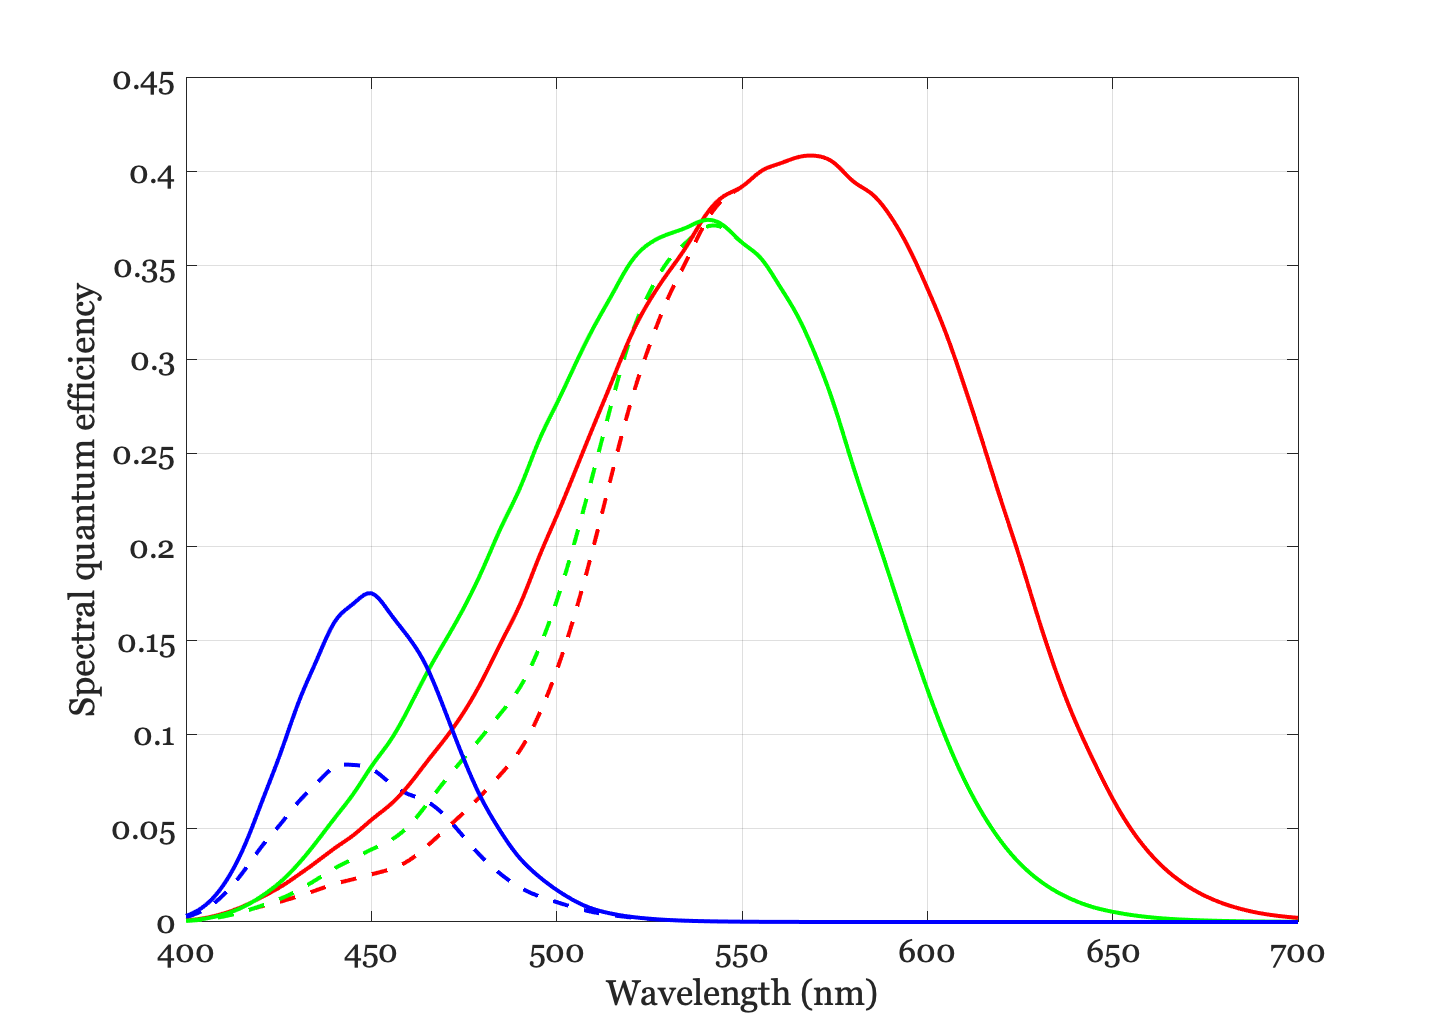

hdl = ieNewGraphWin;

thisColor = [0.6 0.2 0.2; 0.2 0.6 0.2; 0.1 0.1 0.6];

cm.macular.density = 0.35;
cm.plot('spectral qe',[],'lens',thisLens,'hdl',hdl);
p = hdl.Children.Children;
for ii=1:3
    p(ii).LineWidth = 2;
    %    p(ii).Color = thisColor(4-ii,:);
    p(ii).Color = peakColor{4-ii};
    
    p(ii).LineStyle = '--';
end

hold on;
cm.macular.density = 0;
cm.plot('spectral qe',[],'lens',thisLens,'hdl',hdl);
p = hdl.Children.Children;

for ii=1:3
    p(ii).LineWidth = 2;
    %     p(ii).Color = thisColor(4-ii,:);
    p(ii).Color = peakColor{4-ii};
    
    p(ii).LineStyle = '-';
end


% legend({'Density 0.35','Density 0'});

## Figure 10 Show the impact of the macular pigment but with an image

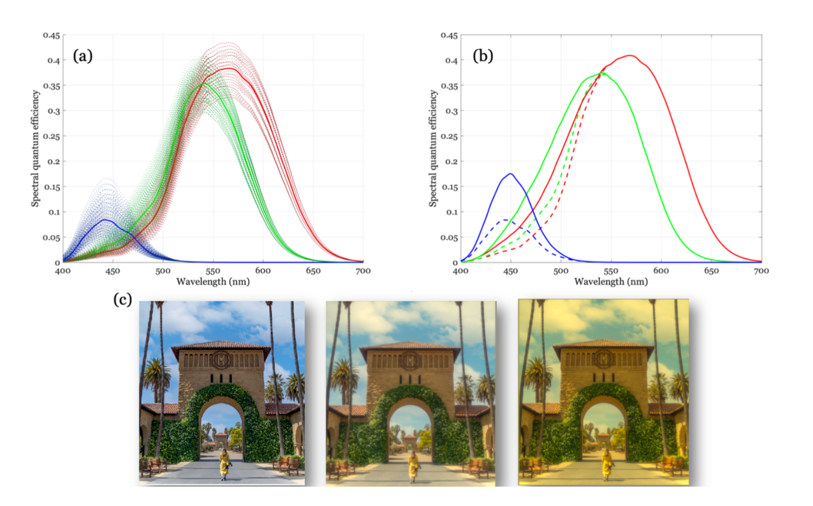

which('stanfordQuadEntryLowRes')

scene = sceneFromFile('stanfordQuadEntryLowRes.png','rgb',100,'reflectance-display',400:10:700);

[vcReadImage] Assuming an 8bit image and a 10 bit LUT


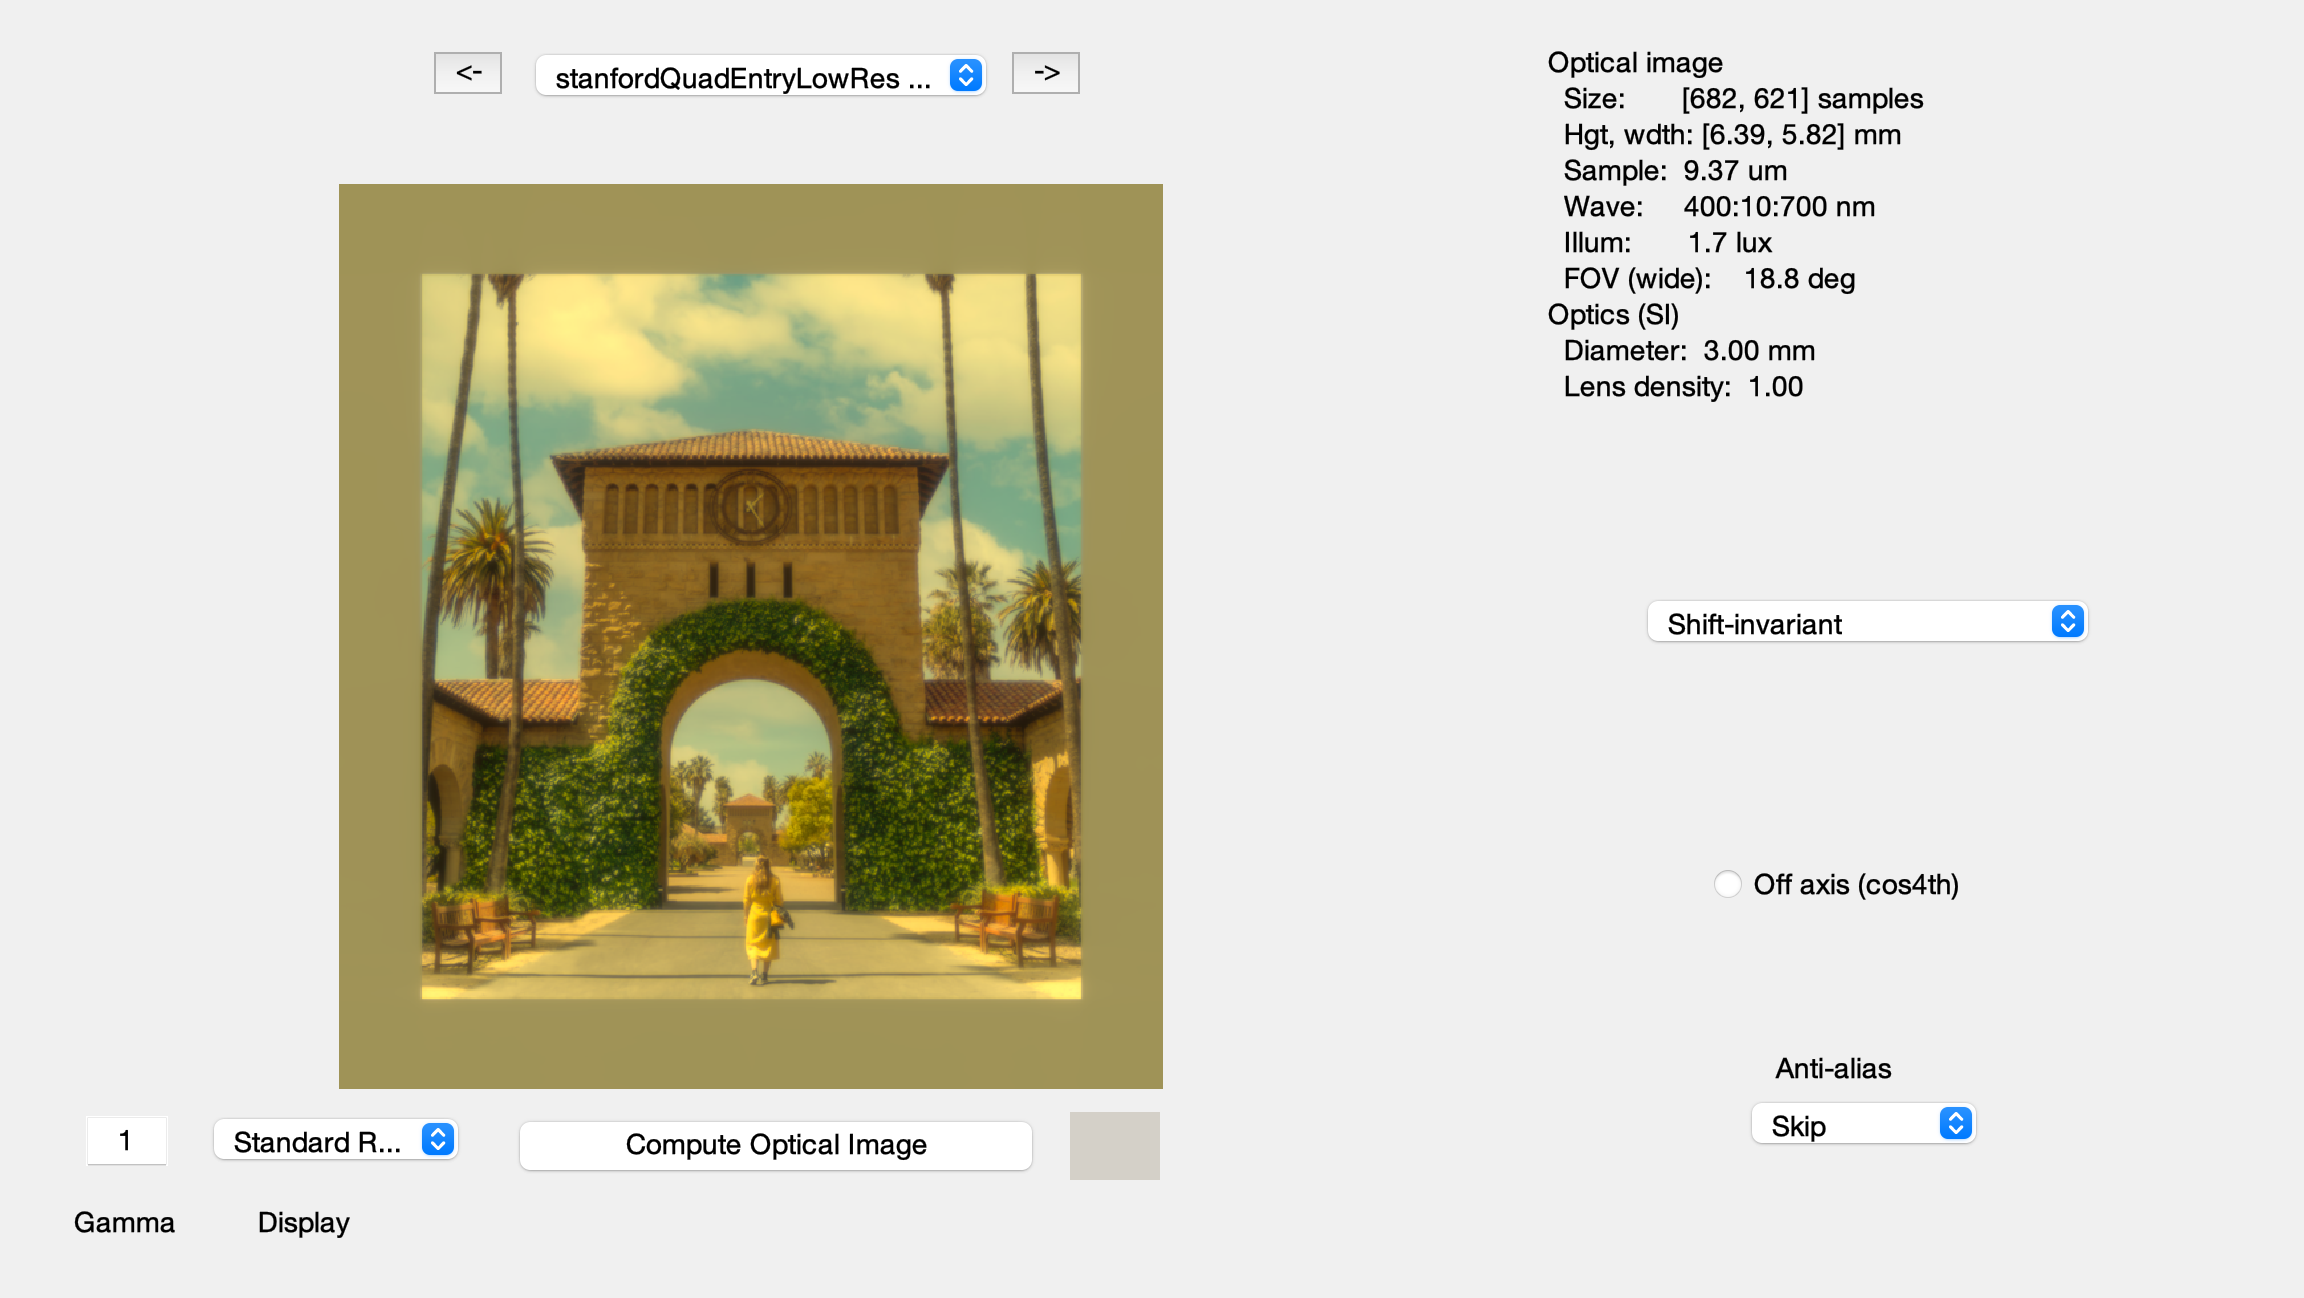

sceneWindow(scene);

% scene = sceneCreate;
oi = oiCreate;
oi = oiCompute(oi,scene);

% Just the lens
oiWindow(oi);

% The lens and macular pigment
thisM = Macular;
t = thisM.transmittance;
photons = oiGet(oi,'photons');
for ii=1:31
    photons(:,:,ii) = photons(:,:,ii)*t(ii);
end
oi = oiSet(oi,'photons',photons);
oiWindow(oi);

## Figure 11